# Lab Assignment 8

#### ### Agam Goyal ###

## Prepare Workspace

close all
clear

load lab8dat.mat

## Item 3

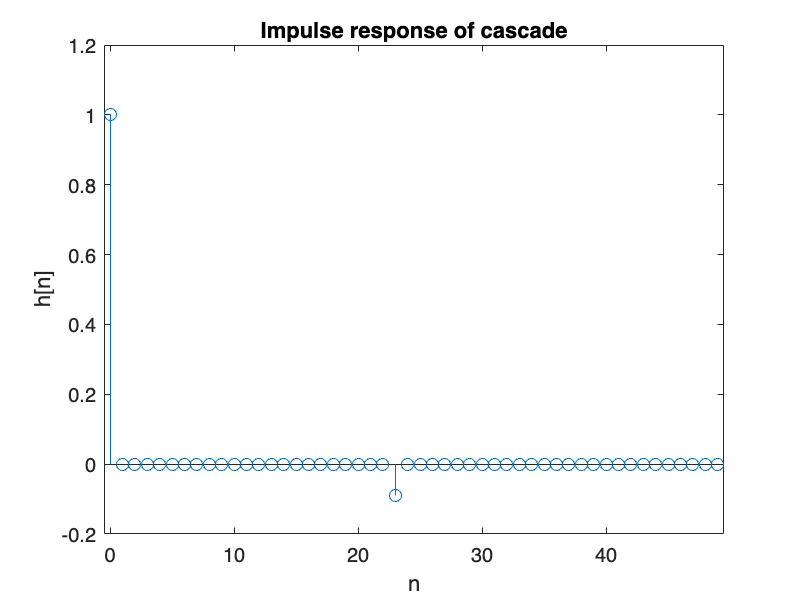

r = 0.9;
M = 22;

b = [1 -r];
b_deconv = r.^[0:M];

h = filter(b_deconv,1,[b zeros(1,48)]);

figure
stem(0:49,h)
xlabel('n')
ylabel('h[n]')
title('Impulse response of cascade')
xlim([-0.5, 49.5])
ylim([-0.2, 1.2])

## Item 4

% Listen to the original audio
soundsc(x2,8000)

% Apply an echo to the speech signal in x2 and listen to it
b = [ 1 zeros(1,1599) 0.9 ];
y2 = filter(b,1,x2);

soundsc(y2,8000)

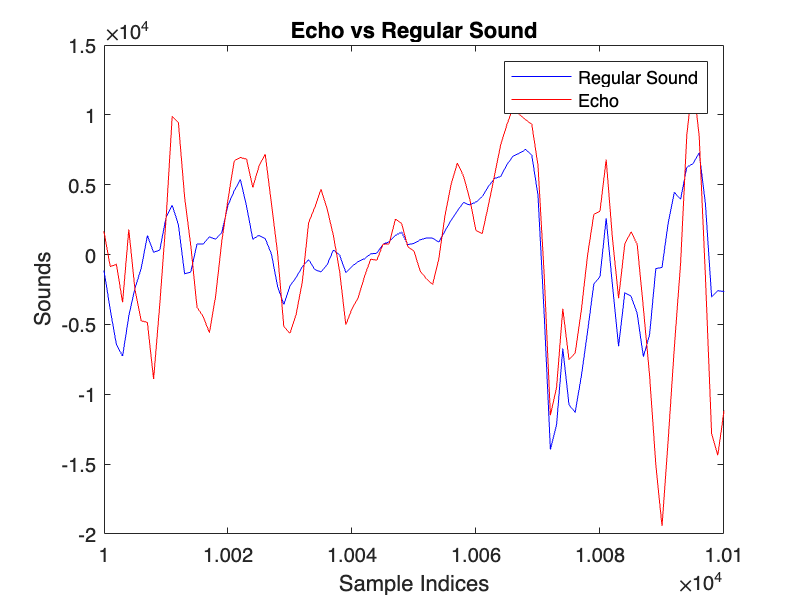

% Plotting
figure
plot(x2, 'Blue')
hold on;
plot(y2, 'Red')
xlabel('Sample Indices')
ylabel('Sounds')
title('Echo vs Regular Sound')
legend('Regular Sound','Echo')
xlim([10000, 10100])
hold off;